clear
clf
load("Experiment 1\Vin.mat")
load("Experiment 1\Iout_ch2.mat")
load("Experiment 1\Iout_ch1.mat")
Ve=0

Ve = 0

Ie=-Iout_ch2;
Ib=Iout_ch1;
Ic=Ie-abs(Ib);
%line of best fit
[first, last, mmax, bmax, Nmax]=linefit(Vin,log(Ic), 5e-6);
 Is = exp(bmax)

Is = 6.1754e-15

 Ut = 1/mmax

Ut = 0.0263

 Ic_theory=Is*exp((Vin-Ve)/Ut);
 [first, last, mmax, bmax, Nmax]=linefit(Vin, log(Ib), 1e-5)

first = 132

last = 137

mmax = 37.9354

bmax = -37.8083

Nmax = 6

B =Is/exp(bmax)

B = 162.4044

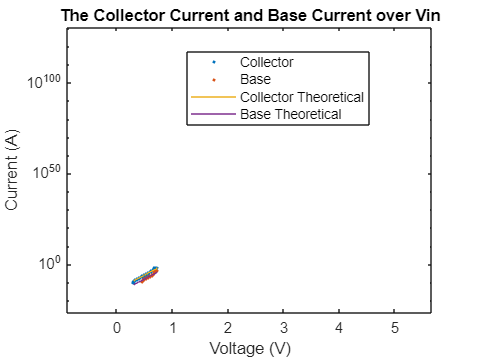

 Ib_theory=Is/B*exp((Vin-Ve)/Ut);
semilogy(Vin,Ic,'.',Vin,Ib,'.',Vin,Ic_theory,Vin,Ib_theory)

title("The Collector Current and Base Current over Vin")
legend('Collector','Base','Collector Theoretical','Base Theoretical')
ylabel("Current (A)")
xlabel("Voltage (V)")

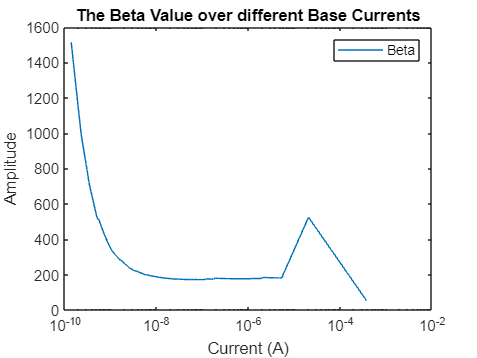

clf
semilogx(Ib,Ic./Ib,'.')
title("The Beta Value over different Base Currents")
legend("Beta")
ylabel("Amplitude")
xlabel("Current (A)")